## Generating Images and Postprocessing

This is a livescript, similar to a jupyter notebook in python. 

Use these controls. Primarly the "Run and Advance" button. 

This document will serve as a reference for running data, in this case the turbulent data.

-Add our paths to our dependency

addpath('plotting_camera');     % Additional codes incase of missing packages. 
addpath('ptvcodes');            % Post Processing codes
addpath('extracodes\')          % Extra codes and helper functions
addpath(genpath('dependency')); % Folder containing a core PTV folder dependency. 

**Generate a new working folder **

% Name of our new working folder 
folder_name = 'JHU_test_new';        % INPUT % 

% No Inputs % 
% Put all new test cases into a folder called "Test Cases" 
folder_path = ['test cases\',folder_name]

folder_path = 'test cases\JHU_test_new'

if exist(folder_path)
    disp('Folder exist')
else
    % make that folder 
    mkdir(folder_path);
    % copy default contents into our new working folder 
    copyfile('dependency\Base_test_folder\',folder_path);
end
% Add new folder path 
addpath(genpath(folder_path));

**Specify our working folder**

% Working folder
work_dir = folder_path;

## Setting up our synthetic Camera configuration:

**1.default_camera**

Setting up the default camera parameters can be done by opening the defaultcamera.m and adjusting the values within the function.

open('defaultCamera.m')

**2. Setting up default camera Arrangement.**

The default camera arrangement is set in the defaultCameraArrangement.m file. 

Setting up the default camera Arrangement can be done by opening the defaultCameraArrangement.m and adjusting the values within the function. The function uses x_p y_p z_p inputs, i.e offsets and deals them out accordingly for each respective camera. 

open('defaultCameraArrangement.m');

or we can generate the structure, then update the values.

CAMERAS = defaultCameraArrangement();
% well make the structure into a table so it easily seen
T = struct2table(CAMERAS);
T(:,1:6)

ans = 4×6 table
    FocalLength    PixelHeight    PixelWidth    PixelRows    PixelColumns    SensorNoiseStd
    ___________    ___________    __________    _________    ____________    ______________

       0.205         1.7e-05       1.7e-05        1024           1024             0.05     
       0.205         1.7e-05       1.7e-05        1024           1024             0.05     
       0.205         1.7e-05       1.7e-05        1024           1024             0.05     
       0.205         1.7e-05       1.7e-05        1024           1024             0.05     


T(:,7:end)

ans = 4×5 table
    SensorNoiseMean    SensorGain              Eye                Center           Up     
    _______________    __________    _______________________    ___________    ___________

         0.05             0.6        -0.05     0.05      0.2    0    0    0    0    1    0
         0.05             0.6         0.05     0.05      0.2    0    0    0    0    1    0
         0.05             0.6        -0.05    -0.05      0.2    0    0    0    0    1    0
         0.05             0.6         0.05    -0.05      0.2    0    0    0    0    1    0


Essentially if we would like to update the camera position for a camera,

we would update the eye of said camera

% Updating camera eye (location of camera)
% For Camera 1 
CAMERAS(1) = setfield(CAMERAS(1),'Eye',[-.05,.05,.2]);
% For Camera 2 
CAMERAS(2) = setfield(CAMERAS(2),'Eye',[.05,.05,.2]);
% For Camera 3 
CAMERAS(3) = setfield(CAMERAS(3),'Eye',[-.05,-.05,.2]);
% For Camera 4 
CAMERAS(4) = setfield(CAMERAS(4),'Eye',[.05,-.05,.2]);
disp('% ---------  Updated Position Tables ---------  %')
% T(:,1:6)
T(:,9)

We can do this for any of the feilds for any of the cameras. 

**Note: Depending on the method you may need to pass in the update objected to **

**future functions. **

## Calibration Images

To generate calibration images we first need to specify the calibration directory:

% Working calibration folder 
cal_dir = [work_dir,'/cal'];

Calibration Images are generated by generating the target points and by rendering the images. 

The target points are generated using  **calibrationTarget.m**

The points are adjusted by adjusting the dot spacing value. When the function is ran, the bounds of the points are 

returned. 

addParameter(p, 'dotSpacing', 0.0032, @isnumeric); %  0.0254,0.032 % XY directions

addParameter(p, 'dotSpacing_z', 0.0016, @isnumeric); %  0.0254,0.032 % Z direction

open('calibrationTarget.m')

[x,y,z, xc, yc, zc] = calibrationTarget();

X-Range:-0.0064      0.0064; Y-Range:-0.0064      0.0064; Z-Range:0      0.0032


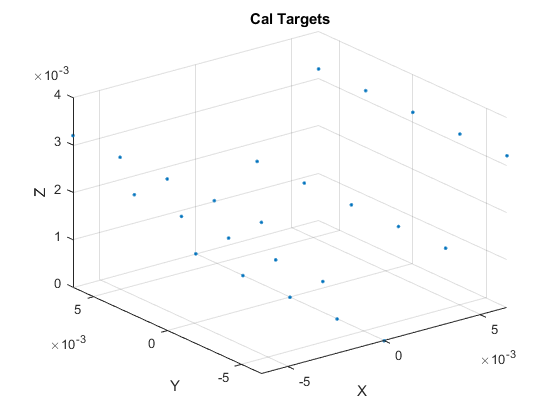

figure
plot3(xc,yc,zc,'.')
xlabel('X');ylabel('Y');zlabel('Z');grid on
title('Cal Targets')

**Using the CalTargetMultiView function, synthetic calibration images can be generated by passing in a few functions. **

**Open the calTargetMultiViw to see the input parameters:**

**The main Parameters:**

addParameter(p, 'plot', true, @islogical); % SHOW IMAGES 

addParameter(p, 'cameras', defaultCameraArrangement(), @isstruct); % Load the cameras 

addParameter(p, 'cal_dir', 'test/cal', @isstr); % Directory to Save files

addParameter(p, 'save', false, @islogical); % Save files 

addParameter(p, 'TargetFile', true, @islogical); % Save Target file for PTV

addParameter(p, 'target_3D', true, @islogical); %  3D Calibration Target. 

addParameter(p, 'plot_camera', false, @islogical); %SHOW CAMERA PLACMENT. 

addParameter(p, 'generate_ori', false, @islogical); % Generate ORI FILES FOR PTV

Then we can generate the calibration images using: 

calTargetMultiView('save',true,'cal_dir',cal_dir,'TargetFile', true,'target_3D',...
true,'generate_ori', true,'plot_camera',true);
% or pass in the camera structure

% calTargetMultiView('cameras',CAMERAS,'save',true,'cal_dir',cal_dir,'TargetFile', true,'target_3D',...
% true,'generate_ori', true,'plot_camera',true);

## Flow Images:

    To generate images of the particle postions, we need to specify the image directory and ensure that the folder is empty. This code will specify said directory, and if it exist already, it will remove it.

img_dir  = [work_dir,'/img'];
if exist(img_dir)
% Remove the exiting img folder
    disp('exist')
    rmdir(img_dir,'s')
    disp('Removed image directory')
end

### Data Structure for Image generation

We need to pass data into the makeImageUniversal function. 

The data must be in a structure with fields,x,y,z. Where x,y,z are matrices containing the particle locations in time. 

Example: if is in the form X = [ 70x100 ] then 70 is the number of time steps and 100 is the number of particles and or trajectories.

Therefore, X(1,:) contains all the X locations of all the particles at time t=1. 

Once we have the matrices X,Y,Z, they must be packed intro a data structure. The data structure follows the form:

test_data.x = X;

test_data.y = Y;

test_data.z = Z ;

**Here, we will use a function which gets the turbulent. **

[X,Y,Z] = Get_turb_data(data_name,time,ntraj)

time = 70;

ntraj = 100

[X,Y,Z] = Get_turb_data('test',70,200);
% scale the data set 
X=.01*X;
Y=.01*Y;
Z=.01*Z;
% SHIFT
X = (X - mean(mean(X)));
Y = (Y - mean(mean(Y)));
Z = (Z - min(min(Z)));
% pack into a structure. 
test_data.x = X;
test_data.y = Y;
test_data.z = Z;

Note we are scaling and shifting the data such that it fits into our synthetic experiment. 

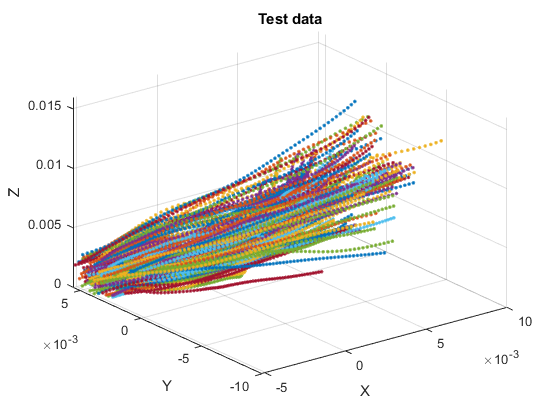

% plot for visual understanding
figure
plot3(X,Y,Z,'.')
title('Test data'); xlabel('X');ylabel('Y');zlabel('Z');grid on

**Then we can generate the images makeImage_universal. **

However, Like many of the other functions we can pass in parameters.

addParameter(p, 'cameras', defaultCameraArrangement(), @isstruct);

addParameter(p, 'outdir', '.', @isstr); % Where to Save 

addParameter(p, 'particleDiameterMean', 2*sqrt(8), @isnumeric); % 1.5 particleDiameterMean

addParameter(p, 'particleDiameterStdDev', 0.10 * sqrt(8), @isnumeric); %  particleDiameterStdDev

addParameter(p, 'beamStdDev', 0.05, @isnumeric); % Beam Standard dev

addParameter(p, 'BeamPlaneZ', 0, @isnumeric); % Bean plane

addParameter(p, 'save', false, @islogical); % Save Images

addParameter(p, 'plot', true, @islogical); % Plot the image sequence as it is rendered?

addParameter(p, 'data', [], @isstruct); % Our input data

**The default values can be modified by passing in the parameter. **

Here we will save the image the image sequence to our out directory, we wont plot the data, and well pass in the

data using 'data' and the test_data structure we made eariler. 

ndim = 70

mdim = 200

    70



On frame 1 of 70


On frame 2 of 70


On frame 3 of 70


On frame 4 of 70


On frame 5 of 70


On frame 6 of 70


On frame 7 of 70


On frame 8 of 70


On frame 9 of 70


On frame 10 of 70


On frame 11 of 70


On frame 12 of 70


On frame 13 of 70


On frame 14 of 70


On frame 15 of 70


On frame 16 of 70


On frame 17 of 70


On frame 18 of 70


On frame 19 of 70


On frame 20 of 70


On frame 21 of 70


On frame 22 of 70


On frame 23 of 70


On frame 24 of 70


On frame 25 of 70


On frame 26 of 70


On frame 27 of 70


On frame 28 of 70


On frame 29 of 70


On frame 30 of 70


On frame 31 of 70


On frame 32 of 70


On frame 33 of 70


On frame 34 of 70


On frame 35 of 70


On frame 36 of 70


On frame 37 of 70


On frame 38 of 70


On frame 39 of 70


On frame 40 of 70


On frame 41 of 70


On frame 42 of 70


On frame 43 of 70


On frame 44 of 70


On frame 45 of 70


On frame 46 of 70


On frame 47 of 70


On frame 48 of 70


On frame 49 of 70


On frame 50 of 70


On frame 51 of 70


On frame 52 of 70


On frame 53 of 70


On frame 54 of 70


On frame 55 of 70


On frame 56 of 70


On frame 57 of 70


On frame 58 of 70


On frame 59 of 70


On frame 60 of 70


On frame 61 of 70


On frame 62 of 70


On frame 63 of 70


On frame 64 of 70


On frame 65 of 70


On frame 66 of 70


On frame 67 of 70


On frame 68 of 70


On frame 69 of 70


On frame 70 of 70


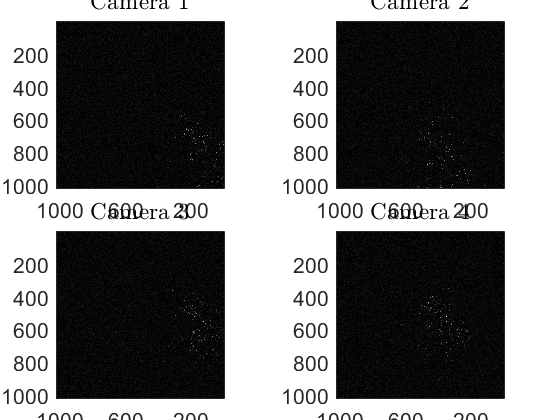

makeImages_universal('outdir',img_dir,'save',true,'plot',true,'data',test_data);


% or pass in the camera 
%makeImages_universal('cameras',CAMERAS','outdir',img_dir,'save',true,'plot',false,'data',test_data);

% Remove the tif 
remove_tif_M(img_dir);

**Go to the PTV folder we created and perform the following steps:**

1. Calibration

2. Tracking

Using default liboptv tracker

step: 10001, curr: 115, next: 117, links: 96, lost: 19, add: 85

step: 10002, curr: 117, next: 215, links: 103, lost: 14, add: 88

step: 10003, curr: 215, next: 217, links: 151, lost: 64, add: 153

step: 10004, curr: 217, next: 273, links: 146, lost: 71, add: 158

step: 10005, curr: 273, next: 278, links: 157, lost: 116, add: 204

step: 10006, curr: 278, next: 335, links: 166, lost: 112, add: 210

step: 10007, curr: 335, next: 335, links: 171, lost: 164, add: 258

step: 10008, curr: 335, next: 388, links: 186, lost: 149, add: 252

step: 10009, curr: 388, next: 381, links: 186, lost: 202, add: 294

step: 10010, curr: 381, next: 423, links: 179, lost: 202, add: 302

step: 10011, curr: 423, next: 431, links: 182, lost: 241, add: 325

step: 10012, curr: 431, next: 459, links: 172, lost: 259, add: 310

step: 10013, curr: 459, next: 439, links: 188, lost: 271, add: 373

step: 10014, curr: 439, next: 510, links: 184, lost: 255, add: 385

step: 10015, curr: 510, next: 522, links: 200, lost: 310, add: 418

step: 10016, curr: 522, next: 552, links: 197, lost: 325, add: 405

step: 10017, curr: 552, next: 542, links: 204, lost: 348, add: 460

step: 10018, curr: 542, next: 602, links: 201, lost: 341, add: 453

step: 10019, curr: 602, next: 587, links: 201, lost: 401, add: 450

step: 10020, curr: 587, next: 583, links: 199, lost: 388, add: 441

step: 10021, curr: 583, next: 581, links: 202, lost: 381, add: 492

step: 10022, curr: 581, next: 632, links: 208, lost: 373, add: 503

step: 10023, curr: 632, next: 646, links: 223, lost: 409, add: 551

step: 10024, curr: 646, next: 696, links: 215, lost: 431, add: 522

step: 10025, curr: 696, next: 670, links: 227, lost: 469, add: 588

step: 10026, curr: 670, next: 738, links: 218, lost: 452, add: 584

step: 10027, curr: 738, next: 733, links: 221, lost: 517, add: 595

step: 10028, curr: 733, next: 747, links: 218, lost: 515, add: 587

step: 10029, curr: 747, next: 741, links: 233, lost: 514, add: 644

step: 10030, curr: 741, next: 794, links: 242, lost: 499, add: 608

step: 10031, curr: 794, next: 759, links: 226, lost: 568, add: 688

step: 10032, curr: 759, next: 845, links: 221, lost: 538, add: 659

step: 10033, curr: 845, next: 811, links: 236, lost: 609, add: 726

step: 10034, curr: 811, next: 891, links: 231, lost: 580, add: 699

step: 10035, curr: 891, next: 858, links: 226, lost: 665, add: 693

step: 10036, curr: 858, next: 851, links: 214, lost: 644, add: 721

step: 10037, curr: 851, next: 870, links: 217, lost: 634, add: 772

step: 10038, curr: 870, next: 935, links: 229, lost: 641, add: 831

step: 10039, curr: 935, next: 991, links: 249, lost: 686, add: 782

step: 10040, curr: 991, next: 933, links: 232, lost: 759, add: 834

step: 10041, curr: 933, next: 998, links: 253, lost: 680, add: 821

step: 10042, curr: 998, next: 975, links: 239, lost: 759, add: 910

step: 10043, curr: 975, next: 1078, links: 252, lost: 723, add: 989

step: 10044, curr: 1078, next: 1159, links: 265, lost: 813, add: 1020

step: 10045, curr: 1159, next: 1189, links: 262, lost: 897, add: 1038

step: 10046, curr: 1189, next: 1212, links: 292, lost: 897, add: 1088

step: 10047, curr: 1212, next: 1260, links: 279, lost: 933, add: 1113

step: 10048, curr: 1260, next: 1285, links: 283, lost: 977, add: 1198

step: 10049, curr: 1285, next: 1375, links: 288, lost: 997, add: 1228

step: 10050, curr: 1375, next: 1402, links: 296, lost: 1079, add: 1233

step: 10051, curr: 1402, next: 1409, links: 298, lost: 1104, add: 1166

step: 10052, curr: 1409, next: 1336, links: 283, lost: 1126, add: 1314

step: 10053, curr: 1336, next: 1487, links: 275, lost: 1061, add: 1347

step: 10054, curr: 1487, next: 1522, links: 312, lost: 1175, add: 1404

step: 10055, curr: 1522, next: 1578, links: 309, lost: 1213, add: 1499

step: 10056, curr: 1578, next: 1681, links: 320, lost: 1258, add: 1536

step: 10057, curr: 1681, next: 1708, links: 324, lost: 1357, add: 1562

step: 10058, curr: 1708, next: 1735, links: 287, lost: 1421, add: 1569

step: 10059, curr: 1735, next: 1749, links: 299, lost: 1436, add: 1600

step: 10060, curr: 1749, next: 1782, links: 314, lost: 1435, add: 1748

step: 10061, curr: 1782, next: 1929, links: 326, lost: 1456, add: 1685

step: 10062, curr: 1929, next: 1862, links: 327, lost: 1602, add: 1817

step: 10063, curr: 1862, next: 1998, links: 333, lost: 1529, add: 1735

step: 10064, curr: 1998, next: 1911, links: 321, lost: 1677, add: 1818

step: 10065, curr: 1911, next: 1993, links: 317, lost: 1594, add: 1745

step: 10066, curr: 1993, next: 1915, links: 310, lost: 1683, add: 1781

step: 10067, curr: 1915, next: 1945, links: 290, lost: 1625, add: 1772

step: 10068, curr: 1945, next: 1936, links: 280, lost: 1665, add: 1786

step: 10069, curr: 1936, next: 1941, links: 230, lost: 1706, add: 69

Average over sequence, particles: 977.3, links: 238.0, lost: 739.3

tracking without display finished

Starting show trajectories

## **Post Processing of the data Sets**

**Read in the data set**

test=[work_dir,'\res'];
% test='C:\Users\alex\Desktop\og\PTV_SYN\test\Copy_of_res';
start = 10001;
last = 10070;
dt=1/100;
min_len = 5;
%------
traj_RC=ptv_is_to_traj(test,start,last,min_len,dt);

Reading ...
Done .
Building trajectories
Done
PTV to Traj


Plot the reconstructed dataset

plot_long_trajectories(traj_RC,min_len);
v = [10 -8 2];
[caz,cel] = view(v)

caz = 51.3402

cel = 8.8764

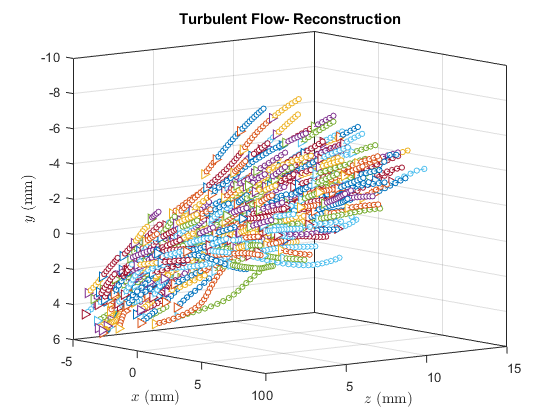

title('Turbulent Flow- Reconstruction')

Get the ground truth data and put into a trajectory structure. 

Scale it by 1000, and plot them next to each other 

traj_GT = pos_to_traj(test_data.x,test_data.y,test_data.z,dt);

traj = struct with fields:
        xf: []
        yf: []
        zf: []
        uf: []
        vf: []
        wf: []
       axf: []
       ayf: []
       azf: []
         t: []
    trajid: []


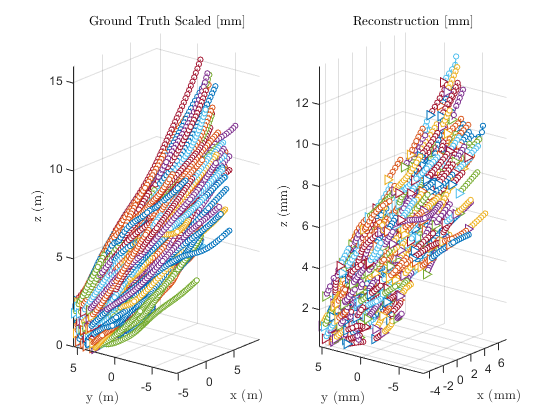

caz = -51.3402

cel = 8.8764

caz = -51.3402

cel = 8.8764

traj_GT_SCALED = scale_traj(traj_GT,1000);
plot_long_traject_COP(traj_GT_SCALED,'Ground Truth Scaled [mm]',traj_RC,'Reconstruction [mm]',min_len)

Lets save the data we processed into the test folder for safe keep!

% Make a folder folder our data call data sets 
data_folder_path = [folder_path,'\Datasets\']

data_folder_path = 'test cases\JHU_test_new\Datasets\'

mkdir(data_folder_path)

% Save the Ground truth Trajactory 
save([data_folder_path,'traj_GT.mat'],'traj_GT')
% Save the Ground Truth Scaled Trajectory 
save([data_folder_path,'traj_GT_SCALED.mat'],'traj_GT_SCALED')
% Save the Reconstuction Trajectory
save([data_folder_path,'traj_RC.mat'],'traj_RC')
% Save the Dataset
save([data_folder_path,'test_data.mat'],'test_data')
% And save the entire workspace work space
save([data_folder_path,'Workspace.mat'])